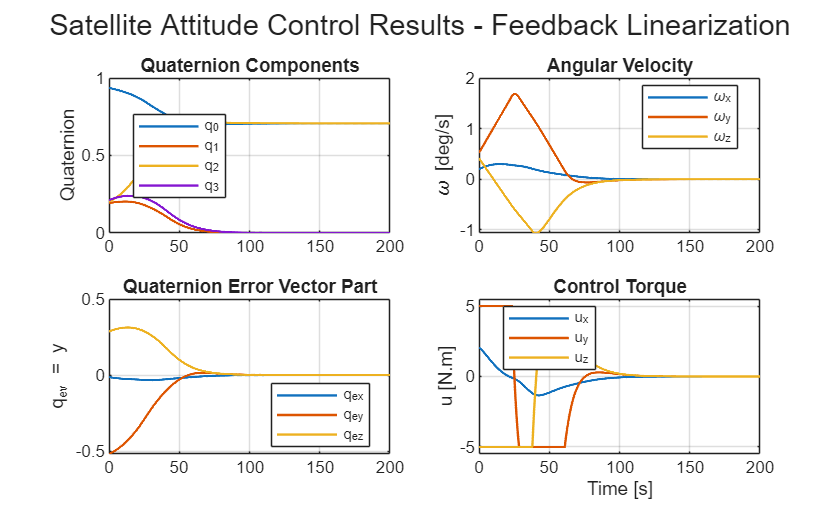

%% Satellite Attitude Control via Feedback Linearization
% This script simulates quaternion-based rigid-body attitude dynamics
% with feedback linearization and PD virtual control.
%
% State definition:
%   q   = [q0; qv]   scalar-first quaternion
%   w   = body angular velocity [rad/s]
%
% Control objective:
%   Drive the quaternion vector part qev -> 0 and angular velocity -> 0

clear; clc; close all;

%% 1) Tuning parameters

% Inertia matrix [kg.m^2]
J = [6540.0   80.2   -415.8;
      80.2  6437.0    469.3;
     -415.8   469.3  7610.0];

% Initial angular velocity [deg/s]
omega0_deg = [0.1979; 0.5235; 0.4151];
omega0 = deg2rad(omega0_deg);

% Initial quaternion (scalar-first)
q0 = [0.9364; 0.1932; 0.2027; 0.2113];
q0 = q0 / norm(q0);

% Desired quaternion (scalar-first)
qd = [sqrt(2); 0; sqrt(2); 0];
qd = qd / norm(qd);

% Desired angular velocity
omega_d = [0; 0; 0];

% Feedback-linearization gains
% Tune these through natural frequency / damping ratio
% Kp = diag([0.50, 0.50, 0.50]);
% Kd = diag([1.20, 1.20, 1.20]);

% Optional second-order design parameters (for reference)
wn   = [1; 1; 1]*0.025*4;      % natural frequencies [rad/s]
zeta = [1; 1; 1];      % damping ratios
Kp = diag(wn.^2);
Kd = diag(2*zeta.*wn);

% Simulation settings
tEnd = 200;
dt   = 0.1;
t    = 0:dt:tEnd;
N    = numel(t);

% Control saturation limits [N.m]
uMax = [5; 5; 5];

% Disturbance settings
useDisturbance = true;
distAmp     = [2e-4; -1.5e-4; 1e-4];   % constant part [N.m]
distSinAmp  = [1e-4; 1e-4; 1e-4];      % sinusoidal amplitude [N.m]
distSinFreq = [0.02; 0.03; 0.025];     % angular frequency [rad/s]

%% 2) Preallocation

q       = zeros(4, N);
omega   = zeros(3, N);
u       = zeros(3, N);
tauDist = zeros(3, N);
qErr    = zeros(4, N);
Bmat    = zeros(3, 3, N);
v_list  = zeros(3, N);
q(:,1)     = q0;
omega(:,1)  = omega0;

%% 3) Main simulation loop

for k = 1:N-1
    tk = t(k);

    % Current states
    qk = q(:,k);
    wk = omega(:,k);

    % Normalize quaternion to avoid numerical drift
    qk = qk / norm(qk);

    % Split quaternion
    q0s = qk(1);
    qv  = qk(2:4);

    % Quaternion error: qe = qd^{-1} ⊗ q
    qe = quatMultiply(quatConj(qd), qk);

    % Enforce positive scalar part for unique representation
    if qe(1) < 0
        qe = -qe;
    end

    qe0 = qe(1);
    qev = qe(2:4);

    qErr(:,k) = qe;

    % B(qe) matrix from the thesis
    B = 0.5 * (qe0*eye(3) + skew3(qev));
    Bmat(:,:,k) = B;

    % Current angular velocity error
    we = wk - omega_d;

    % Quaternion kinematics of the error model
    % qev_dot = 0.5*(qe0*I + qev^x)*we
    qev_dot = B * we;

    % Compute qe0_dot using scalar quaternion kinematics
    % qe0_dot = -0.5*qev' * we
    qe0_dot = -0.5 * (qev.' * we);

    % Compute Bdot(qe) = 0.5*(qe0_dot*I + qev_dot^x)
    Bdot = 0.5 * (qe0_dot*eye(3) + skew3(qev_dot));

    % Disturbance torque
    if useDisturbance
        tauDist(:,k) = distAmp + distSinAmp .* sin(distSinFreq * tk);
    else
        tauDist(:,k) = zeros(3,1);
    end

    % Nonlinear terms from the feedback-linearized output dynamics
    % y = qev
    % yddot = alpha(x) + beta(x)u + d(x,t)
    alpha = Bdot * wk - B * (J \ (skew3(wk) * J * wk));
    beta  = B * (J \ eye(3));

    % Virtual input for closed-loop second-order dynamics
    % v = -Kd*y_dot - Kp*y
    v = -Kd * qev_dot - Kp * qev;
    v_list(:, k) = v;
    % Nominal feedback-linearizing control law
    % u = beta^{-1} (v - alpha - d)
    % Since disturbance is not directly canceled in the nominal law,
    % the disturbance enters the closed-loop dynamics as a residual term.
    d_term = B * (J \ tauDist(:,k));

    if rcond(beta) < 1e-12
        warning('beta matrix is ill-conditioned at t = %.3f s', tk);
        u_unsat = zeros(3,1);
    else
        u_unsat = beta \ (v - alpha - d_term);
    end

    % Apply actuator saturation
    u(:,k) = min(max(u_unsat, -uMax), uMax);

    % Rigid-body rotational dynamics
    wdot = J \ (-skew3(wk) * J * wk + u(:,k) + tauDist(:,k));

    % Quaternion kinematics
    qdot0 = -0.5 * (qv.' * wk);
    qdotv =  0.5 * (q0s*eye(3) + skew3(qv)) * wk;
    qdot   = [qdot0; qdotv];

    % Explicit Euler integration
    omega(:,k+1) = wk + dt * wdot;
    q(:,k+1)     = qk + dt * qdot;
    q(:,k+1)     = q(:,k+1) / norm(q(:,k+1));
end

% Fill last sample for post-processing consistency
q(:,N) = q(:,N) / norm(q(:,N));
qeLast = quatMultiply(quatConj(qd), q(:,N));
if qeLast(1) < 0
    qeLast = -qeLast;
end
qErr(:,N) = qeLast;

if useDisturbance
    tauDist(:,N) = distAmp + distSinAmp .* sin(distSinFreq * t(N));
end

% Recompute last control torque for plotting
qk = q(:,N);
wk = omega(:,N);
q0s = qk(1);
qv  = qk(2:4);
qe  = qErr(:,N);
qe0 = qe(1);
qev = qe(2:4);

B = 0.5 * (qe0*eye(3) + skew3(qev));
we = wk - omega_d;
qev_dot = B * we;
qe0_dot  = -0.5 * (qev.' * we);
Bdot = 0.5 * (qe0_dot*eye(3) + skew3(qev_dot));

alpha = Bdot * wk - B * (J \ (skew3(wk) * J * wk));
beta  = B * (J \ eye(3));

d_term = B * (J \ tauDist(:,N));
v = -Kd * qev_dot - Kp * qev;

if rcond(beta) < 1e-12
    u(:,N) = zeros(3,1);
else
    u(:,N) = min(max(beta \ (v - alpha - d_term), -uMax), uMax);
end

%% 4) Performance metrics

attErrAngle = zeros(1,N);
for k = 1:N
    qe_k = qErr(:,k);
    attErrAngle(k) = 2 * acos(max(min(qe_k(1),1),-1));
end
attErrAngle_deg = rad2deg(attErrAngle);

%% 5) Plots

% Main results
figure('Name','Satellite Attitude Control Results','Color','w');
sgtitle('Satellite Attitude Control Results - Feedback Linearization');

subplot(2,2,1);
plot(t, q(1,:), 'LineWidth', 1.2); hold on;
plot(t, q(2,:), 'LineWidth', 1.2);
plot(t, q(3,:), 'LineWidth', 1.2);
plot(t, q(4,:), 'LineWidth', 1.2);
grid on;
ylabel('Quaternion');
legend('q_0','q_1','q_2','q_3','Location','best');
title('Quaternion Components');

subplot(2,2,2);
plot(t, rad2deg(omega(1,:)), 'LineWidth', 1.2); hold on;
plot(t, rad2deg(omega(2,:)), 'LineWidth', 1.2);
plot(t, rad2deg(omega(3,:)), 'LineWidth', 1.2);
grid on;
ylabel('\omega [deg/s]');
legend('\omega_x','\omega_y','\omega_z','Location','best');
title('Angular Velocity');

subplot(2,2,3);
plot(t, qErr(2,:), 'LineWidth', 1.2); hold on;
plot(t, qErr(3,:), 'LineWidth', 1.2);
plot(t, qErr(4,:), 'LineWidth', 1.2);
grid on;
ylabel('q_{ev} = y');
legend('q_{ex}','q_{ey}','q_{ez}','Location','best');
title('Quaternion Error Vector Part');

subplot(2,2,4);
plot(t, u(1,:), 'LineWidth', 1.2); hold on;
plot(t, u(2,:), 'LineWidth', 1.2);
plot(t, u(3,:), 'LineWidth', 1.2);
ylim([-1.1 1.1]*uMax(1))
grid on;
ylabel('u [N.m]');
xlabel('Time [s]');
legend('u_x','u_y','u_z','Location','best');
title('Control Torque');

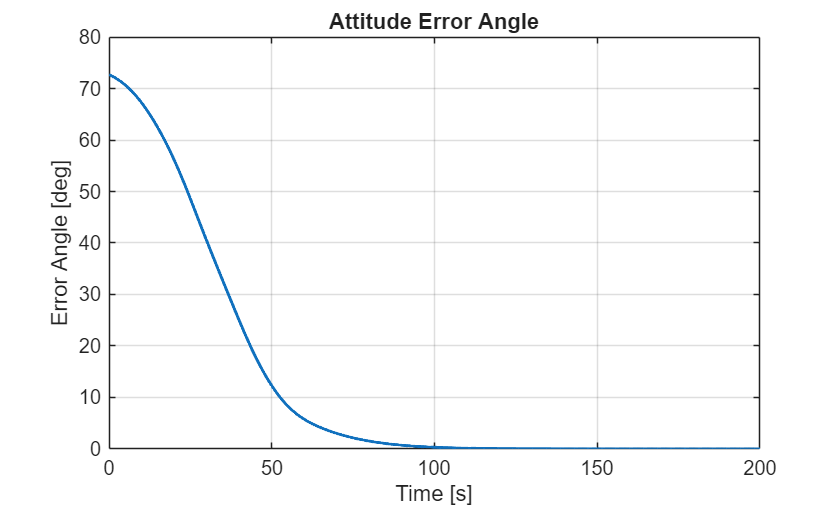


figure('Name','Attitude Error Angle','Color','w');
plot(t, attErrAngle_deg, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('Error Angle [deg]');
title('Attitude Error Angle');

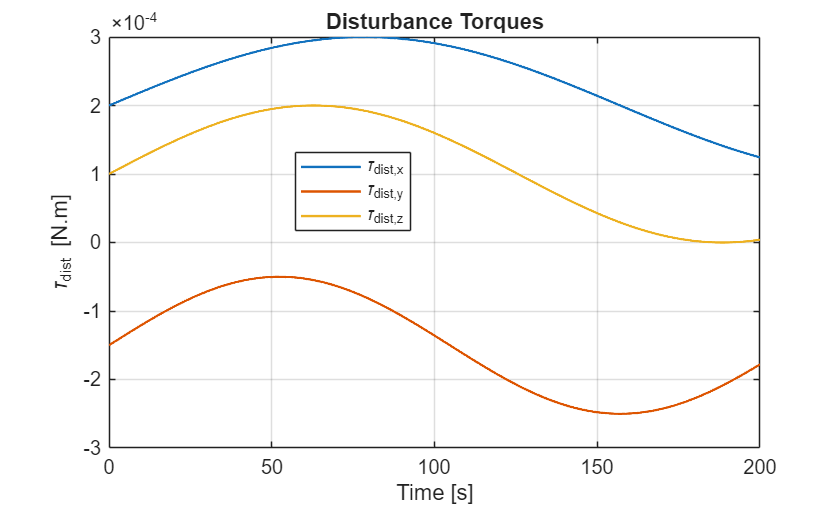


figure('Name','Disturbance Torques','Color','w');
plot(t, tauDist(1,:), 'LineWidth', 1.2); hold on;
plot(t, tauDist(2,:), 'LineWidth', 1.2);
plot(t, tauDist(3,:), 'LineWidth', 1.2);
grid on;
xlabel('Time [s]');
ylabel('\tau_{dist} [N.m]');
legend('\tau_{dist,x}','\tau_{dist,y}','\tau_{dist,z}','Location','best');
title('Disturbance Torques');


%% 6) Local functions

function S = skew3(v)
% Return the 3x3 skew-symmetric matrix of a 3x1 vector
S = [   0   -v(3)  v(2);
      v(3)    0   -v(1);
     -v(2)  v(1)    0 ];
end

function qc = quatConj(q)
% Quaternion conjugate for scalar-first quaternion
qc = [q(1); -q(2:4)];
end

function q = quatMultiply(q1, q2)
% Quaternion multiplication for scalar-first convention
w1 = q1(1); v1 = q1(2:4);
w2 = q2(1); v2 = q2(2:4);

w = w1*w2 - dot(v1, v2);
v = w1*v2 + w2*v1 + cross(v1, v2);

q = [w; v];
end
